# Panel models with no cross section linkages

Tutorial file for testing panel models

## Housekeeping

clear
close all
clear classes

rehash path

import separable.*  


## Convenience functions

percentiles = [10, 50, 90];

prctileFunc = @(x) prctile(x, percentiles, 2);

extremesFunc = @(x) [min(x, [], 2), max(x, [], 2)];

medianFunc = @(x) median(x, 2);

flatFunc = @(x) x(:, :);

defaultColors = get(0, "defaultAxesColorOrder");


## Number of Samples

numPresampled = 100;

## Prepare meta information for the models

Note that the meta information is common to all panel BVAR models, regardless of the specific estimator used.

The properties are as follows:

**endogenousConcepts **–  a list of endogenous variables, listed without the country suffix. Plays the same role as **endogenousNames** in plain BVARs

**units **– a list of countries/units that share the same endogenous variables


estimStart = datex("1972-Q1");
estimEnd = datex("2014-Q4");
estimSpan = datex.span(estimStart, estimEnd);

meta = Meta( ...
    endogenousConcepts=["YER", "HICSA", "STN"], ...
    units=["US", "EA"], ...
    exogenous=["Oil"], ...
    order=4, ...
    intercept=true, ...
    estimationSpan=estimSpan, ...
    identificationHorizon=12, ...
    shockConcepts=["DEM", "SUP", "POL"] ...
);



## Specifying and loading input data


inputTbl = tablex.fromFile("panelData.csv");
dataH = DataHolder(meta, inputTbl);

## Reduced form models

#### OLS Mean Group Panel

There is no estimator specific settings.

estimatorR1 = estimator.MeanOLSPanel(meta);

#### Bayesian Pooled Panel with Normal-Wishart priors

There is no estimator specific settings.

%estimatorR1 = estimator.NormalWishartPanel(meta);

#### Zellner- Hong Random Effect Panel

There is no estimator specific settings.

%estimatorR1 = estimator.ZellnerHongPanel(meta);

#### Hierarchical Panel

**S0 (0.001)** – The shape of the Inverse Gamma distribution of overal tightness

**V0 (0.001)** – The scale of the Inverse Gamma distribution of overal tightness

% estimatorR1 = estimator.HierarchicalPanel(meta);

### Creating the reduced form model


modelR1 = ReducedForm( ...
    meta=meta, ...
    dataHolder=dataH, ...
    estimator=estimatorR1 ...
);

## Estimation/sampling of the reduced form model 


modelR1.initialize();
info0 = modelR1.presample(numPresampled);


 Presampling from posterior (MeanOLSPanel) [100]
 ――――――――――――――――――――――――――――――――――――――――――――――――――  100% 



modelR1.Presampled{1}.beta

ans =     1.0558
    0.1001
    0.0037
   -0.0183
   -0.3062
   -0.2788
   -0.4686
    0.2751
    0.1914
    0.2388


## Running Unconditional forecast 

### Settig up the forecast range and run the forecast

fcastStart = datex.shift(modelR1.Meta.EstimationEnd, -10); %The forecast starts 10 periods prior to the end of the estimation span.
fcastEnd = datex.shift(modelR1.Meta.EstimationEnd, 0); %The forecast ends at the end of the estimation window.
fcastSpan = datex.span(fcastStart, fcastEnd);

fcastStart, fcastEnd

fcastStart = datetime
   2012-Q2


fcastEnd = datetime
   2014-Q4



fcastTbx = modelR1.forecast(fcastSpan);
fcastPrctileTbx = tablex.apply(fcastTbx, prctileFunc);
fcastPrctileTbx = tablex.flatten(fcastPrctileTbx); %keeping only the pctiles set at the beginning of the file (10, 50, 90)



### Visualize the unconditional forecast

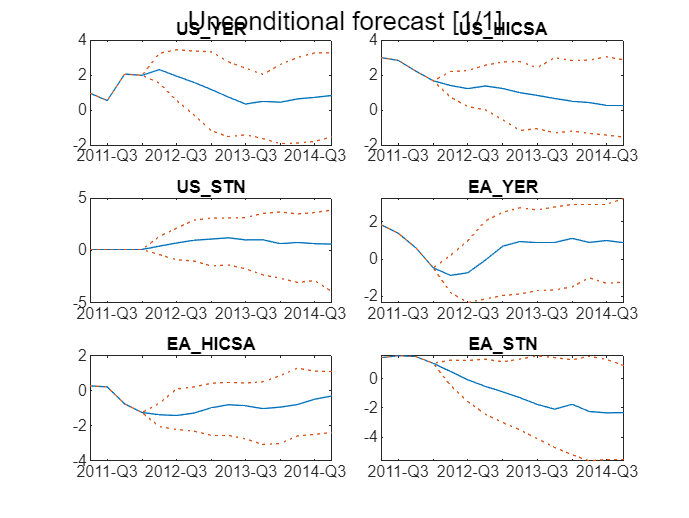

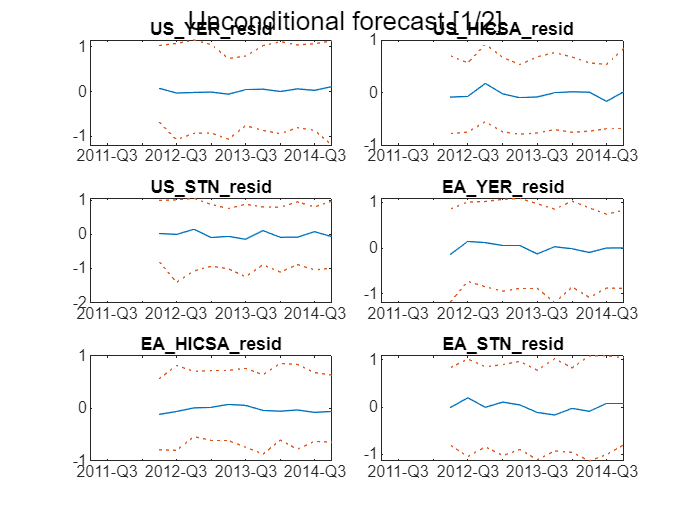

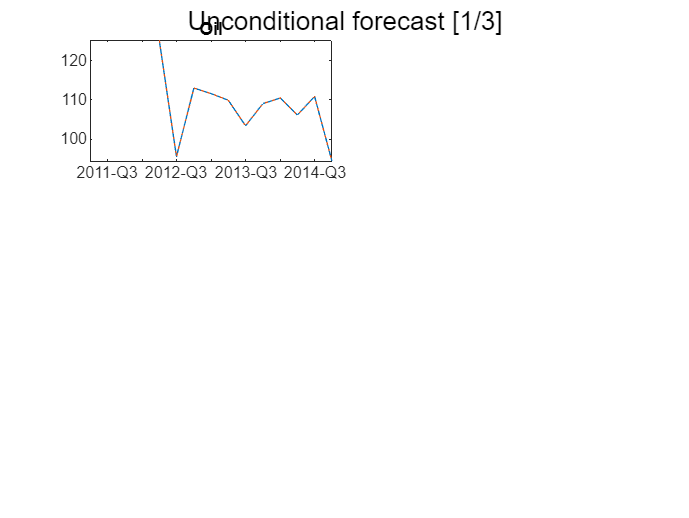

ans = 1×3 cell array
    {1×1 Figure}    {1×1 Figure}    {1×1 Figure}



chartpack.forecastPercentiles( ...
    fcastPrctileTbx, modelR1, FigureTitle ="Unconditional forecast")

## Identification

### Cholesky

#### Seting up the identifier

identChol = identifier.Cholesky(order=[]);

modelS1 = Structural(reducedForm=modelR1, identifier=identChol);
modelS1.initialize();

info1 = modelS1.presample(numPresampled);


 Presampling from posterior (MeanOLSPanel) [100]
 ――――――――――――――――――――――――――――――――――――――――――――――――――  100% 



modelS1.Presampled{1}

ans = struct with fields:
                  beta: [42×1 double]
                 sigma: [3×3 double]
                  bhat: [42×1 double]
    IdentificationDraw: [1×1 struct]
                     D: [3×3×2 double]


#### Checking transition matrices

modelS1.Presampled{1}.IdentificationDraw

ans = struct with fields:
        A: {12×1 cell}
        C: {12×1 cell}
    Sigma: [3×3×2 double]


modelS1.Presampled{1}.IdentificationDraw.A{1,1}

ans = ans(:,:,1) =

    1.0708   -0.0318    0.2061
    0.0804    0.9073    0.0852
    0.1017    0.0606    1.2465
   -0.1778    0.1448   -0.1960
   -0.0558   -0.0330    0.0986
   -0.2983   -0.1362   -0.4246
   -0.2650   -0.2365    0.0389
    0.3573    0.1910    0.0089
    0.0823   -0.0346    0.1632
    0.0450    0.1261    0.0171
   -0.1834   -0.1877   -0.0085
    0.0913    0.0906   -0.0082


ans(:,:,2) =

    1.0708   -0.0318    0.2061
    0.0804    0.9073    0.0852
    0.1017    0.0606    1.2465
   -0.1778    0.1448   -0.1960
   -0.0558   -0.0330    0.0986
   -0.2983   -0.1362   -0.4246
   -0.2650   -0.2365    0.0389
    0.3573    0.1910    0.0089
    0.0823   -0.0346    0.1632
    0.0450    0.1261    0.0171
   -0.1834   -0.1877   -0.0085
    0.0913    0.0906   -0.0082


modelS1.Presampled{1}.IdentificationDraw.A{2,1}

ans = ans(:,:,1) =

    1.0708   -0.0318    0.2061
    0.0804    0.9073    0.0852
    0.1017    0.0606    1.2465
   -0.1778    0.1448   -0.1960
   -0.0558   -0.0330    0.0986
   -0.2983   -0.1362   -0.4246
   -0.2650   -0.2365    0.0389
    0.3573    0.1910    0.0089
    0.0823   -0.0346    0.1632
    0.0450    0.1261    0.0171
   -0.1834   -0.1877   -0.0085
    0.0913    0.0906   -0.0082


ans(:,:,2) =

    1.0708   -0.0318    0.2061
    0.0804    0.9073    0.0852
    0.1017    0.0606    1.2465
   -0.1778    0.1448   -0.1960
   -0.0558   -0.0330    0.0986
   -0.2983   -0.1362   -0.4246
   -0.2650   -0.2365    0.0389
    0.3573    0.1910    0.0089
    0.0823   -0.0346    0.1632
    0.0450    0.1261    0.0171
   -0.1834   -0.1877   -0.0085
    0.0913    0.0906   -0.0082


#### Checking scaling matrix

modelS1.Presampled{1}.D

ans = ans(:,:,1) =

    0.7501    0.2113    0.1842
         0    0.5079    0.0440
         0         0    0.7030


ans(:,:,2) =

    0.7501    0.2113    0.1842
         0    0.5079    0.0440
         0         0    0.7030


modelS1.Presampled{2}.D

ans = ans(:,:,1) =

    0.7501    0.2113    0.1842
         0    0.5079    0.0440
         0         0    0.7030


ans(:,:,2) =

    0.7501    0.2113    0.1842
         0    0.5079    0.0440
         0         0    0.7030


## Impulse respones (IRF)

### Cholesky

respTbl1 = modelS1.simulateResponses();
respTbl1 = tablex.apply(respTbl1, prctileFunc);


  (MeanOLSPanel) [100]
 ――――――――――――――――――――――――――――――――――――――――――――――――――  100% 



respTbl1 = tablex.flatten(respTbl1);

respTbl1


respTbl1 = 16×18 timetable
     Time                 US_YER___DEM                             US_YER___SUP                               US_YER___POL                           US_HICSA___DEM                         US_HICSA___SUP                         US_HICSA___POL                       US_STN___DEM                       US_STN___SUP                        US_STN___POL                         EA_YER___DEM                             EA_YER___SUP                               EA_YER___POL                           EA_HICSA___DEM                         EA_HICSA___SUP                         EA_HICSA___POL                       EA_STN___DEM                       EA_STN___SUP          

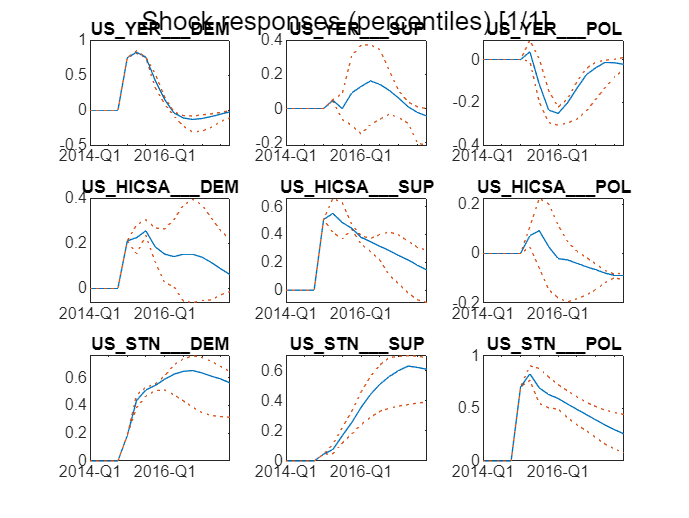

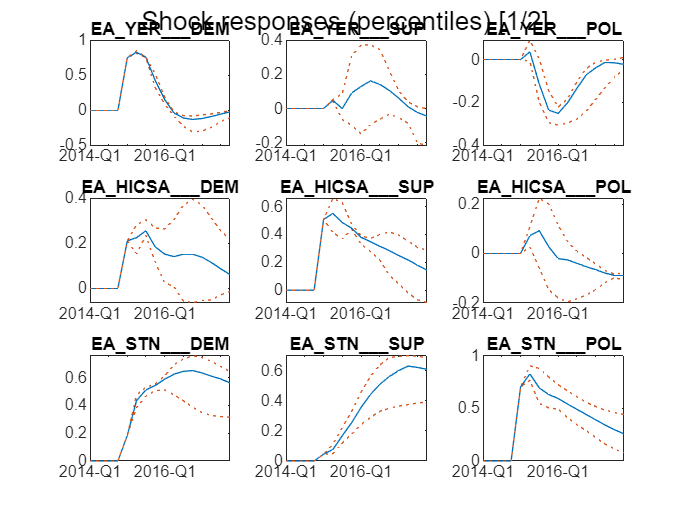


chartpack.responsePercentiles( ...
    respTbl1, modelS1 ...
    , "figureTitle", "Shock responses (percentiles)" ...
);


## **Historical shock decomposition**


histContTbx = modelS1.calculateContributions();

tablex.getHigherDims(histContTbx)

ans = 1×1 cell array
    {["DEM"    "SUP"    "POL"    "Exogenous"    "Initials"]}


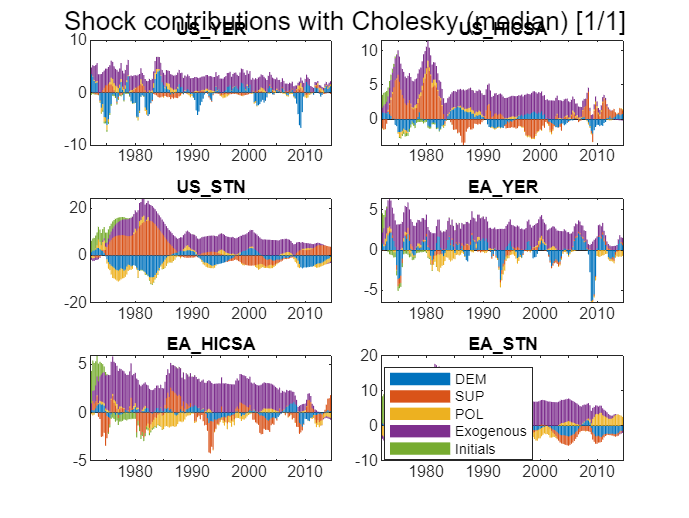


histContMedTbx = tablex.apply(histContTbx, medianFunc);

chartpack.contributionsMedian( ...
    histContMedTbx, modelS1 ...
    , "figureTitle", "Shock contributions with Cholesky (median)" ...
);

## **Unconditional forecast shock decomposition**


[uncFcastTbl1, uncFcastContribTbl1] = modelS1.forecast( ...
    fcastSpan, ...
    contributions=true ...
);

tablex.getHigherDims(uncFcastContribTbl1)

ans = 1×1 cell array
    {["DEM"    "SUP"    "POL"    "Exogenous"    "Initials"]}


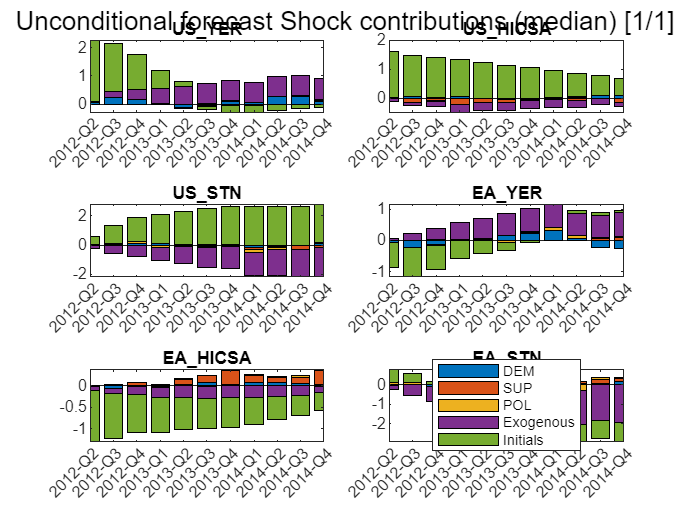


contMedTbx = tablex.apply(uncFcastContribTbl1, medianFunc);

chartpack.contributionsMedian( ...
    contMedTbx,modelS1 ...
    , "figureTitle", "Unconditional forecast Shock contributions (median)" ...
);

## **FEVD**


fevdTbx = modelS1.calculateFEVD();


  (MeanOLSPanel) [100]
 ――――――――――――――――――――――――――――――――――――――――――――――――――  100% 




tablex.getHigherDims(fevdTbx)

ans = 1×1 cell array
    {["DEM"    "SUP"    "POL"]}


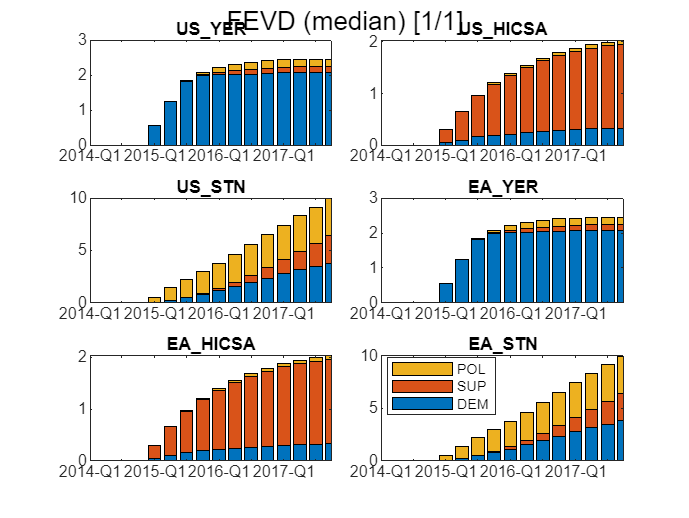


fevdMedTbx = tablex.apply(fevdTbx, medianFunc);

chartpack.contributionsMedian( ...
    fevdMedTbx,modelS1 ...
    , "figureTitle", "FEVD (median)" ...
);

## Conditional forecast

### Settig up the conditions and the forecast plan

condDataTbl = tablex.fromFile("condDataTblPanel.xlsx");
planTbl = tablex.readConditioningPlan("planTblPanel.xlsx");

### Settig up the forecast range 

cfcastStart = datex.shift(modelR1.Meta.EstimationEnd, 1); %The forecast starts after the estimation span.
cfcastEnd = datex.shift(modelR1.Meta.EstimationEnd, 12); 
cfcastSpan = datex.span(cfcastStart, cfcastEnd);

### Running conditional forecast with no simulation plan

[condFcastTbl1, condFcastContribTbl1] = modelS1.conditionalForecast( ...
    cfcastSpan, ...
    conditions=condDataTbl, ...
    plan=[], ...
    exogenousFrom = "conditions" ...
);


 Conditional forecast [100]
 ――――――――――――――――――――――――――――――――――――――――――――――――――  100% 




condFcastPrctilesTbl1 = tablex.apply(condFcastTbl1, prctileFunc);

### Running conditional forecast with simulation plan

[condFcastTbl2, condFcastContribTbl2] = modelS1.conditionalForecast( ...
    cfcastSpan, ...
    conditions=condDataTbl, ...
    plan=planTbl, ...
    exogenousFrom = "conditions" ...
);


 Conditional forecast [100]
 ――――――――――――――――――――――――――――――――――――――――――――――――――  100% 




condFcastPrctilesTbl2 = tablex.apply(condFcastTbl2, prctileFunc);

### Visualize the conditional forecast

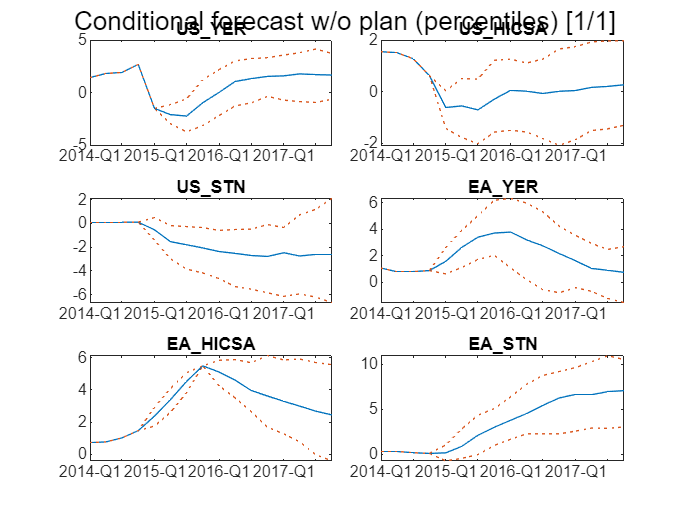

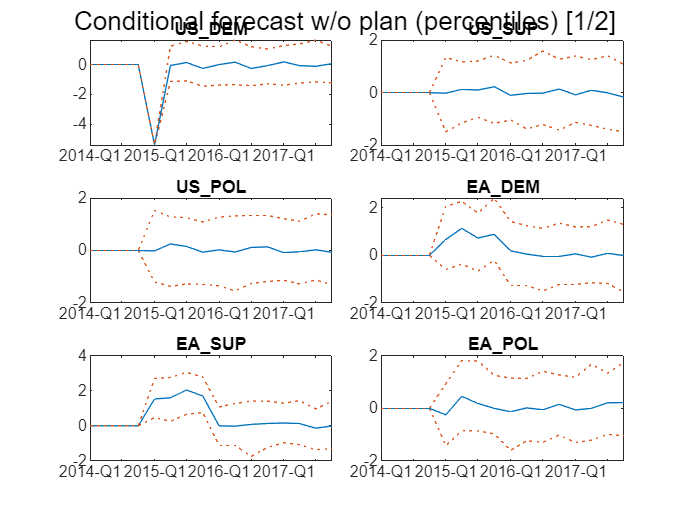

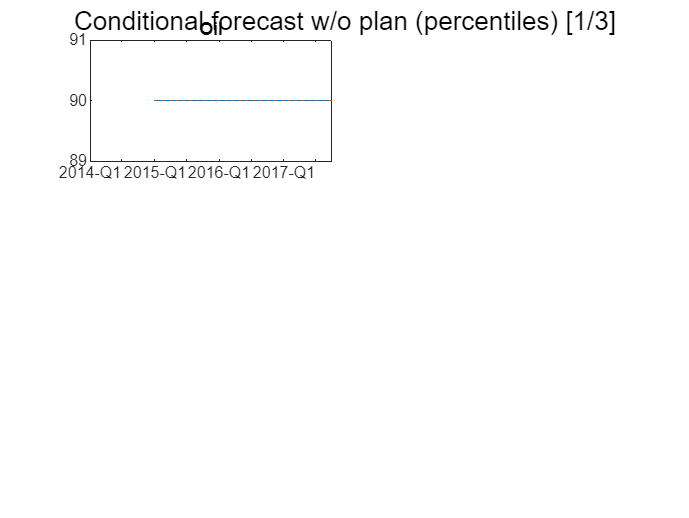

chartpack.conditionalForecastPercentiles( ...
    condFcastPrctilesTbl1,modelS1 ...
    , "figureTitle", "Conditional forecast w/o plan (percentiles)" ...
);

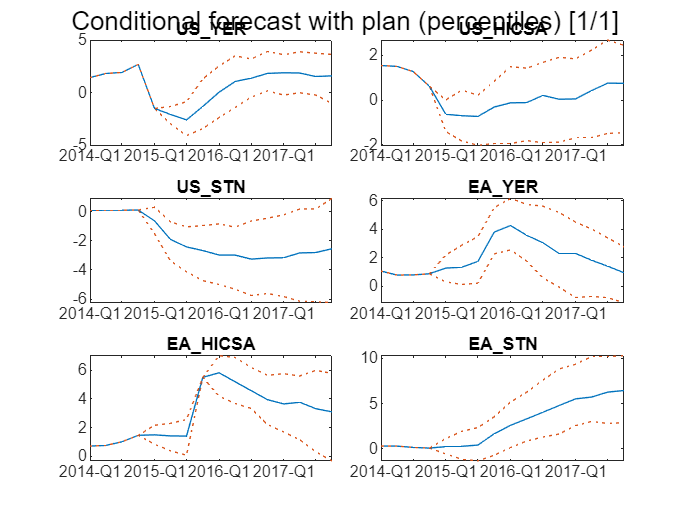

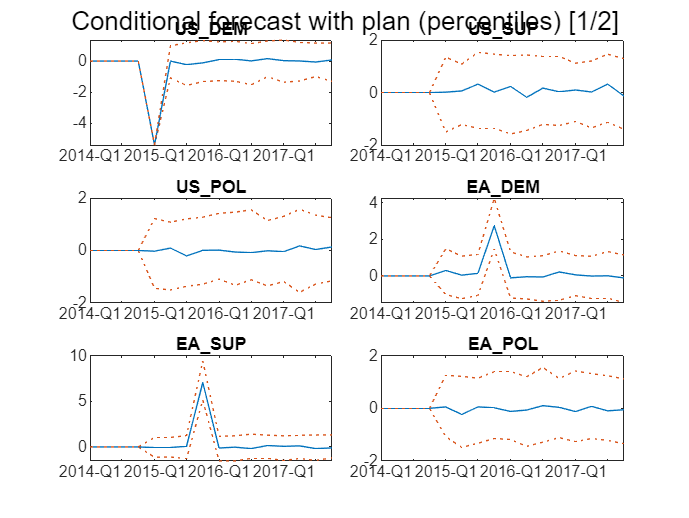

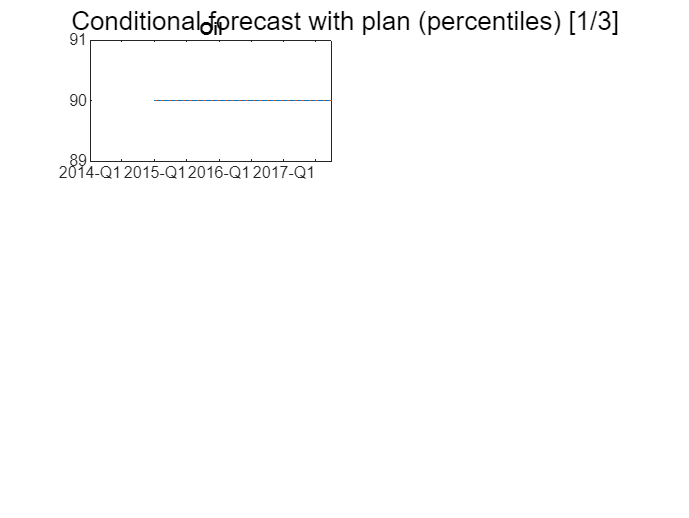


chartpack.conditionalForecastPercentiles( ...
    condFcastPrctilesTbl2,modelS1 ...
    , "figureTitle", "Conditional forecast with plan (percentiles)" ...
);